# Data Preparation

clc
clear all
close all
rng(0)

Topology = 'M2C';

if strcmp(Topology, 'M3C')
    A = [1  1  1  0  0  0  0  0  0;
         0  0  0  1  1  1  0  0  0;
         0  0  0  0  0  0  1  1  1;
        -1  0  0 -1  0  0 -1  0  0;
         0 -1  0  0 -1  0  0 -1  0;
         0  0 -1  0  0 -1  0  0 -1];
elseif strcmp(Topology, 'M2C')
    A = [1  1  1  0  0  0;
         0  0  0  1  1  1;
        -1  0  0 -1  0  0;
         0 -1  0  0 -1  0;
         0  0 -1  0  0 -1];
end

pinvA = pinv(A);
m     = size(A, 2);
N     = null(A, 'rational');
n     = size(N, 2);
pinvN = pinv(N);

# Load data from random data generator

buffer_name       = 'train10k_v2';
buffer_train      = load(strcat(['ImitationLearning\TrainingData\Data\', buffer_name, '.mat']), 'buffer').buffer;
buffer_validation = load('ImitationLearning\TrainingData\Data\validation_v2.mat', 'buffer').buffer;

buffer_train

buffer_train = struct with fields:
    X: [14×10000 double]
    Y: [3×10000 double]

buffer_validation

buffer_validation = struct with fields:
    X: [14×1000 double]
    Y: [3×1000 double]


buffer   = struct();
buffer.X = [buffer_train.X, buffer_validation.X];
buffer.Y = [buffer_train.Y, buffer_validation.Y];

X = buffer.X;
Y = buffer.Y;

Nsamples = size(X, 2)

Nsamples = 11000

Ninputs  = size(X, 1)

Ninputs = 14

Noutputs = size(Y, 1)

Noutputs = 3

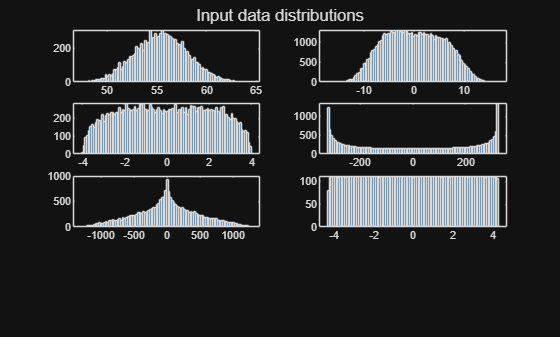


figure
subplot(4, 2, 1)
histogram(X(1, :), 100) % mean(Ec)
subplot(4, 2, 2)
histogram(X(2:1+m, :), 100) % Ec-mean(Ec)
subplot(4, 2, 3)
histogram(X(2+m:3+m, :), 100) % vyac, vybc
subplot(4, 2, 4)
histogram(X(4+m:5+m, :), 100) % iya, iyb
subplot(4, 2, 5)
histogram(X(6+m:7+m, :), 100) % py1, py2
if strcmp(Topology, 'M3C')
    subplot(4, 2, 6)
    histogram(X(8+m:9+m, :), 100)   % ixa, ixb
    subplot(4, 2, 7)
    histogram(X(10+m:11+m, :), 100) % vxac, vxbc
    subplot(4, 2, 8)
    histogram(X(12+m:end, :), 100)  % px1, px2
elseif strcmp(Topology, 'M2C')
    subplot(4, 2, 6)
    histogram(X(8+m, :), 100) % ix
end
sgtitle('Input data distributions')

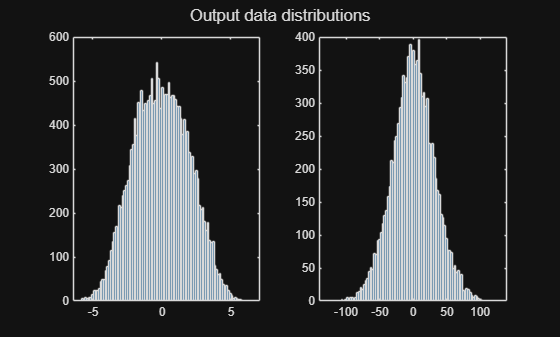


figure
subplot(1, 2, 1)
histogram(Y(1:n, :), 100)
subplot(1, 2, 2)
histogram(Y(end, :), 100)
sgtitle('Output data distributions')

Absolute maximum L.I. circulating and basic currents (assuming ie_ref_max~ie_max)

iya = X(4+m, :);
iyb = X(5+m, :);
iyc = -(iya + iyb);

if strcmp(Topology, 'M3C')
    ixa = X(8+m, :);
    ixb = X(9+m, :);
    ixc = -(ixa + ixb);
    ixy = [ixa; ixb; ixc; iya; iyb; iyc];
elseif strcmp(Topology, 'M2C')
    ixa = X(8+m, :);
    ixb = -ixa;
    ixy = [ixa; ixb; iya; iyb; iyc];
end

iB = pinvA * ixy;
max(abs(iB(:)))

ans = 280.6347


ie = Y(1:n, :);
ie_max = max(abs(ie(:)))

ie_max = 6.4251

Input/outputs limits

Ax0 = 4*130/2;
Ay0 = 380*sqrt(2/3)*30/50;
[ix_max, iy_max, is_max, vo_max, vB_max, VCdiff, eta] = max_values(Ax0, Ay0, 'M2C')

ix_max = 4.2960

iy_max = 4

is_max = 8.5000

vo_max = 223.0806

vB_max = 446.1612

VCdiff = 0.1000

eta = 1.4416

Csm = 987e-6;
Nsm = 4;
C = Csm / Nsm;
vc_mean_ref = vB_max + vo_max;

Emean = C/2 * vc_mean_ref^2;                    % mean(Ec)
Ediff = Emean * ((1+VCdiff)^2 - 1) *ones(m, 1); % Ec-mean(Ec)
IY    = iy_max                     *ones(2, 1); % iya, iyb
VY    = sqrt(3) * Ay0              *ones(2, 1); % vyac, vybc
PY    = VY .* IY;                               % py1, py2

if strcmp(Topology, 'M3C')
    IX = ix_max        *ones(2, 1); % ixa, ixb
    VX = sqrt(3) * Ax0 *ones(2, 1); % vxac, vxbc
    PX = VX .* IX;                  % px1, px2

    Xmax = [Emean; Ediff; IY; VY; PY; IX; VX; PX]
elseif strcmp(Topology, 'M2C')
    IX = ix_max;                    % ix

    Xmax = [Emean; Ediff; IY; VY; PY; IX]
end

Xmax = 1.0e+03 *

    0.0553
    0.0116
    0.0116
    0.0116
    0.0116
    0.0116
    0.0116
    0.0040
    0.0040
    0.3224
    0.3224
    1.2898
    1.2898
    0.0043



IE = is_max *ones(n, 1); % LICCs
VO = vo_max;             % CMV

Ymax = [IE; VO]

Ymax =     8.5000
    8.5000
  223.0806


# Preprocessing

Input/output sizes

size(X)

ans =           14       11000


size(Y)

ans =            3       11000


Normalization

X = X ./ Xmax;
X(1, :) = X(1, :) - 1;
X(1, :) = X(1, :) / VCdiff;
Y = Y ./ Ymax;
% Y = clip(Y, -1, 1);

Training/validation split

X_tr  = buffer_train.X ./ Xmax;
X_tr(1, :) = X_tr(1, :) - 1;
Y_tr  = buffer_train.Y ./ Ymax;
X_val = buffer_validation.X ./ Xmax;
X_val(1, :) = X_val(1, :) - 1;
Y_val = buffer_validation.Y ./ Ymax;

Data augmentation with white noise

% X_tr = [X_tr, X_tr+0.01*randn(size(X_tr))]
% Y_tr = [Y_tr, Y_tr]

Transform to dlarray

dlX     = dlarray(X, 'CB');
dlY     = dlarray(Y, 'CB');
dlX_tr  = dlarray(X_tr, 'CB');
dlY_tr  = dlarray(Y_tr, 'CB');
dlX_val = dlarray(X_val, 'CB');
dlY_val = dlarray(Y_val, 'CB');
dsX_tr  = arrayDatastore(dlX_tr, 'IterationDimension', 2);
dsY_tr  = arrayDatastore(dlY_tr, 'IterationDimension', 2);
dsXY_tr = combine(dsX_tr, dsY_tr);

# Exploratory data analysis

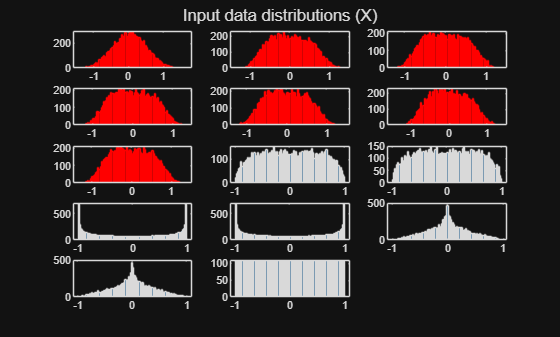

n_cols = 3;

figure
for idx = 1:Ninputs
    subplot(ceil(Ninputs / n_cols), n_cols, idx);
    if max(abs(X(idx, :))) > 1
        histogram(X(idx, :), 100, 'FaceColor', 'red', 'EdgeColor', 'red');
    else
        histogram(X(idx, :), 100);
    end
    % title(['X', num2str(idx)]);
    % ylabel('Freq');
end
sgtitle('Input data distributions (X)')

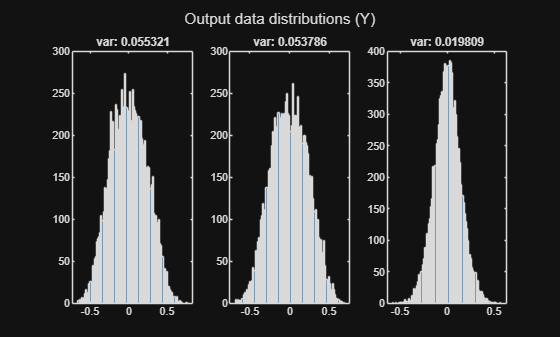


figure
for idx = 1:Noutputs
    subplot(ceil(Noutputs / n_cols), n_cols, idx)
    if max(abs(Y(idx, :))) > 1
        histogram(Y(idx, :), 100, 'FaceColor', 'red', 'EdgeColor', 'red')
    else
        histogram(Y(idx, :), 100)
    end
    title(sprintf('var: %f', var(Y(idx, :))))
end
sgtitle('Output data distributions (Y)')

# Dimensionality reduction for state space visualization

## PCA

Input

% [coeff, score, latent] = pca(X');
% 
% figure
% subplot(1, 2 ,1)
% scatter(score(:, 1), score(:, 2), 10, 'filled', 'MarkerFaceAlpha', 0.1);
% title('2D');
% xlabel('pca_1');
% ylabel('pca_2');
% 
% subplot(1, 2, 2)
% scatter3(score(:, 1), score(:, 2), score(:, 3), 10, 'filled', 'MarkerFaceAlpha', 0.1);
% title('3D');
% xlabel('pca_1');
% ylabel('pca_2');
% zlabel('pca_3');
% 
% sgtitle('PCA X')

Output

% [coeff, score, latent] = pca(Y');
% 
% figure
% subplot(1, 2, 1)
% scatter(score(:, 1), score(:, 2), 10, 'filled', 'MarkerFaceAlpha', 0.1);
% title('2D');
% xlabel('pca_1');
% ylabel('pca_2');
% 
% subplot(1, 2, 2)
% scatter3(score(:, 1), score(:, 2), score(:, 3), 10, 'filled', 'MarkerFaceAlpha', 0.1);
% title('3D');
% xlabel('pca_1');
% ylabel('pca_2');
% zlabel('pca_3');
% 
% sgtitle('PCA Y')

## Clustering

% n_clusters = 5; % Número de clusters
% epsilon = 0.1;  % Radio máximo para DBSCAN
% minPts = 5;     % Mínimo número de puntos para DBSCAN
% 
% % K-means
% [idx_kmeans, C_kmeans] = kmeans(Y', n_clusters, 'Replicates', 10);
% 
% % DBSCAN
% idx_dbscan = dbscan(Y', epsilon, minPts);
% 
% % GMM
% gmm = fitgmdist(Y', n_clusters, 'RegularizationValue', 1e-5);
% idx_gmm = cluster(gmm, Y');
% 
% % PCA
% num_dims = 3;
% [coeff, score, latent] = pca(Y');
% X_reduced = score(:, 1:num_dims);
% 
% figure
% 
% % K-means
% subplot(1, 3, 1)
% scatter3(X_reduced(:, 1), X_reduced(:, 2), X_reduced(:, 3), 10, idx_kmeans, 'filled');
% title('K-means'); xlabel('pca_1'); ylabel('pca_2'); zlabel('pca_3');
% 
% % DBSCAN
% subplot(1, 3, 2)
% scatter3(X_reduced(:, 1), X_reduced(:, 2), X_reduced(:, 3), 10, idx_dbscan, 'filled');
% title('DBSCAN'); xlabel('pca_1'); ylabel('pca_2'); zlabel('pca_3');
% 
% % GMM
% subplot(1, 3, 3)
% scatter3(X_reduced(:, 1), X_reduced(:, 2), X_reduced(:, 3), 10, idx_gmm, 'filled');
% title('GMM'); xlabel('pca_1'); ylabel('pca_2'); zlabel('pca_3');
% 
% sgtitle('Clustering in Original Space');

## UMAP

% pyenv('Version', '3.12', 'ExecutionMode', 'OutOfProcess')
% system('pip install umap-learn')

2D

% code =  [
%           "import umap"
%           "import numpy as np"
%           "reducer = umap.UMAP(n_neighbors=15, min_dist=0.001, n_components=2)"
%           "Xumap = reducer.fit_transform(np.transpose(X))"
%         ];
% 
% code = strjoin(code, newline);
% 
% Xumap = double(pyrun(code, 'Xumap', X=X));
% Yumap = double(pyrun(code, 'Xumap', X=Y));
% 
% figure;
% subplot(1, 2, 1);
% scatter(Xumap(:, 1), Xumap(:, 2), 1, 'filled');
% colormap(jet);
% title('UMAP X');
% xlabel('umap_1'); ylabel('umap_2'); grid on;
% 
% subplot(1, 2, 2);
% scatter(Yumap(:, 1), Yumap(:, 2), 1, 'filled');
% colormap(jet);
% title('UMAP Y');
% xlabel('umap_1'); ylabel('umap_2'); grid on;

3D

% code =  [
%           "import umap"
%           "import numpy as np"
%           "reducer = umap.UMAP(n_neighbors=15, min_dist=0.001, n_components=3)"
%           "Xumap = reducer.fit_transform(np.transpose(X))"
%         ];
% 
% code = strjoin(code, newline);
% 
% Xumap = double(pyrun(code, 'Xumap', X=X));
% Yumap = double(pyrun(code, 'Xumap', X=Y));
% 
% figure;
% subplot(1, 2, 1);
% scatter3(Xumap(:, 1), Xumap(:, 2), Xumap(:, 3), 1, 'filled');
% colormap(jet);
% title('UMAP X');
% xlabel('umap_1'); ylabel('umap_2'); zlabel('umap_3'); grid on;
% 
% subplot(1, 2, 2);
% scatter3(Yumap(:, 1), Yumap(:, 2), Yumap(:, 3), 1, 'filled');
% colormap(jet);
% title('UMAP Y');
% xlabel('umap_1'); ylabel('umap_2'); zlabel('umap_3'); grid on;